This live script is associated with Hasterok, D., M. Gard, C.M.B. Bishop, and D. Kelsey, (submitted to Computers & Geosciences), Chemical identification of metamorphic protoliths using machine learning methods.

This live script plots the results of machine learning classification of metamorphic protoliths using major element chemistry.  The code training_analysis.m plots the results from all classifiers and datasets.

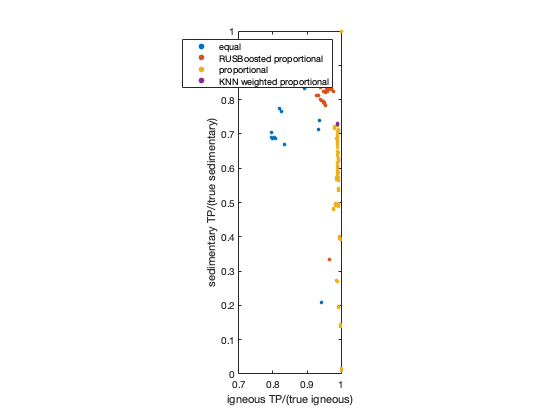

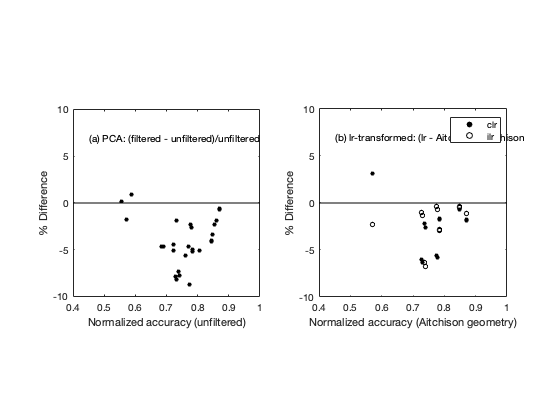

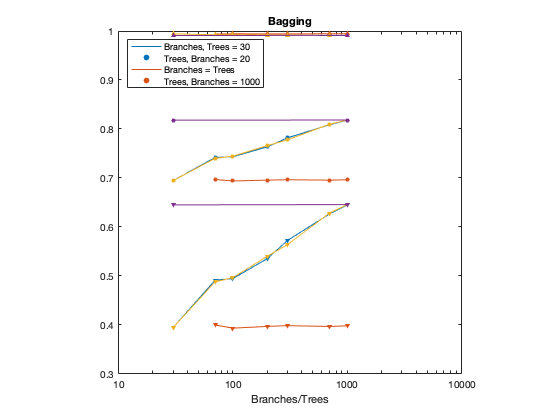

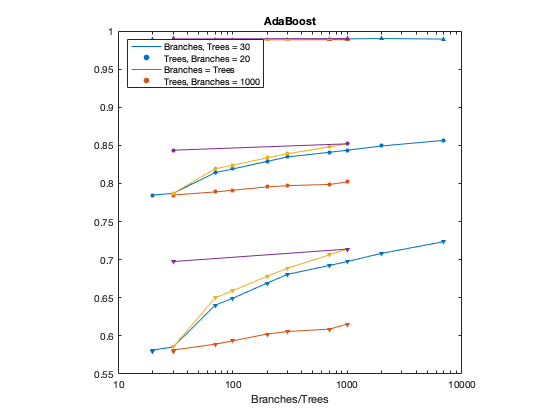

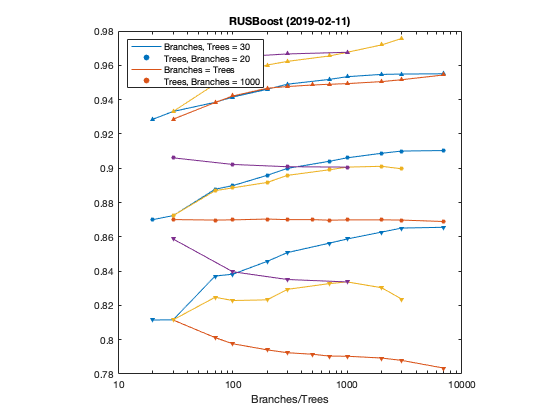

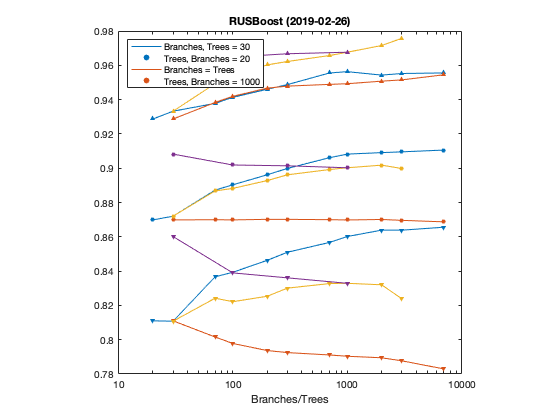

close all;
clear all;

training_analysis;

Results of the preferred classifier RUSBoost with 30 learners and 1000 splits.  The classifier data file includes the raw data used to perform the classification without PCA, and with 10% of the data held in reserve for validation of the reported classifier accuracy.  The data table also includes ilr transormed coordinates.

       & & predicted protolith
       & total & igneous & sedimentary
{\it training dataset}
igneous &  447669 &  428440 &   19229 
sedimentary &   32355 &    3258 &   29097 
{\it validation dataset}
igneous &   49732 &   47475 &    2257 
sedimentary &    3604 &     530 &    3074 


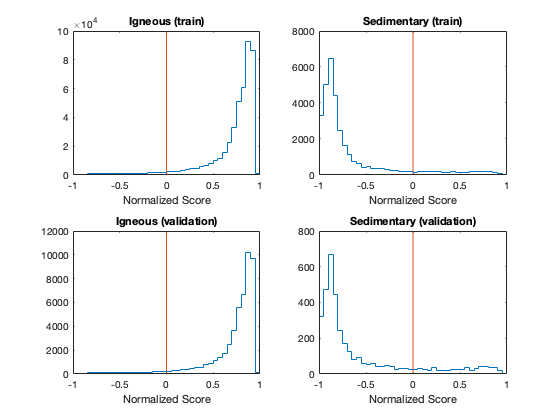

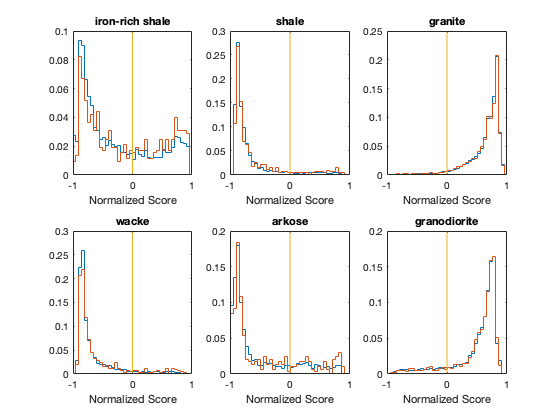

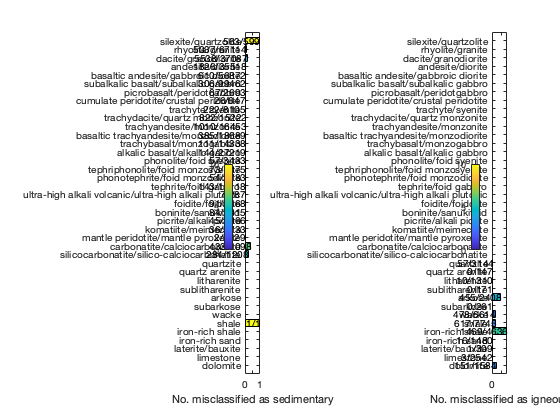


rock type & TN & FN & FN percent
silexite/quartzolite &    36 &   563 & 94.0
rhyolite/granite & 62077 &  5037 & 7.5
dacite/granodiorite & 31549 &  5538 & 14.9
andesite/diorite & 33692 &  1826 & 5.1
basaltic andesite/gabbroic diorite & 56262 &   610 & 1.1
subalkalic basalt/subalkalic gabbro & 99156 &   306 & 0.3
picrobasalt/peridotgabbro &  2626 &    67 & 2.5
cumulate peridotite/crustal peridotite &   621 &    26 & 4.0
trachyte/syenite &  7883 &   222 & 2.7
trachydacite/quartz monzonite & 14400 &   822 & 5.4
trachyandesite/monzonite & 15443 &  1010 & 6.1
basaltic trachyandesite/monzodiorite & 18304 &   385 & 2.1
trachybasalt/monzogabbro & 14227 &   111 & 0.8
alkalic basalt/alkalic gabbro & 27075 &   144 & 0.5
phonolite/foid syenite &  3376 &    57 & 1.7
tephriphonolite/foid monzosyenite &  1802 &    73 & 3.9
phonotephrite/foid monzodiorite &  2729 &    54 & 1.9
tephrite/foid gabbro & 12975 &   143 & 1.1
ultra-high alkali volcanic/ultra-high alkali plutonic &   280 &     7 & 2.4
foidite

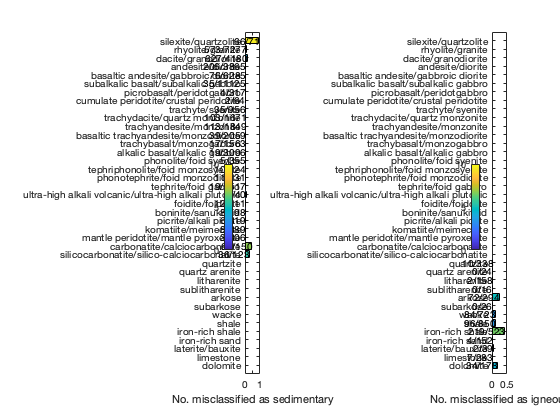


rock type & TN & FN & FN percent
silexite/quartzolite &     5 &    66 & 93.0
rhyolite/granite &  6704 &   573 & 7.9
dacite/granodiorite &  3553 &   627 & 15.0
andesite/diorite &  3659 &   206 & 5.3
basaltic andesite/gabbroic diorite &  6209 &    76 & 1.2
subalkalic basalt/subalkalic gabbro & 11090 &    35 & 0.3
picrobasalt/peridotgabbro &   313 &     4 & 1.3
cumulate peridotite/crustal peridotite &    62 &     2 & 3.1
trachyte/syenite &   921 &    35 & 3.7
trachydacite/quartz monzonite &  1568 &   103 & 6.2
trachyandesite/monzonite &  1736 &   113 & 6.1
basaltic trachyandesite/monzodiorite &  2020 &    39 & 1.9
trachybasalt/monzogabbro &  1546 &    17 & 1.1
alkalic basalt/alkalic gabbro &  3077 &    19 & 0.6
phonolite/foid syenite &   350 &     5 & 1.4
tephriphonolite/foid monzosyenite &   214 &    10 & 4.5
phonotephrite/foid monzodiorite &   320 &    11 & 3.3
tephrite/foid gabbro &  1498 &    19 & 1.3
ultra-high alkali volcanic/ultra-high alkali plutonic &    36 &     4 & 10.0
foidit

load('classifier_data_2019-02-26_ilr.mat');
load('trained_RUSBoost_Model_30l_1000s_20190226');

tree_analysis(protolithClassifier,traindata,testdata);